% Laplacian Filter

close all;
clear all;
clc;

imgr= imread("E:\Study\DIP\Lab_exp\cameraman.jpg");
imgr =rgb2gray(imgr)

imgr = 512×512 uint8 matrix
   159   158   158   157   156   155   155   155   158   158   158   158   158   158   158   158   156   156   157   157   156   157   158   159   159   160   159   160   162   159   157   160   165   162   160   161   161   160   160   161   163   162   161   162   164   165   164   162   160   161
   156   156   157   158   158   157   156   155   158   158   158   158   158   158   158   158   157   157   157   157   156   156   158   159   158   159   158   159   162   159   156   160   164   162   160   161   161   160   160   161   162   161   160   161   163   163   162   161   160   161
   156   156   156   156   157   157   157   157   158   158   158   158   158   158   158   158   158   158   158   157   156   156   157   158   158   159   158   158   161   158   156   159   164   161   160   161   161   160   159   160   161   160   159   160   161   162   161   160   160   161
   159   157   155   154   154   156   158   159   158   158   158   

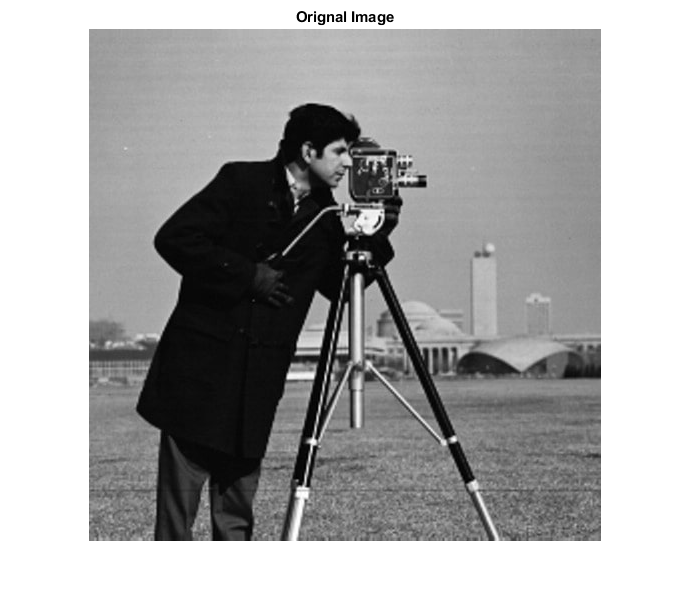

imshow(imgr);
title('Orignal Image')

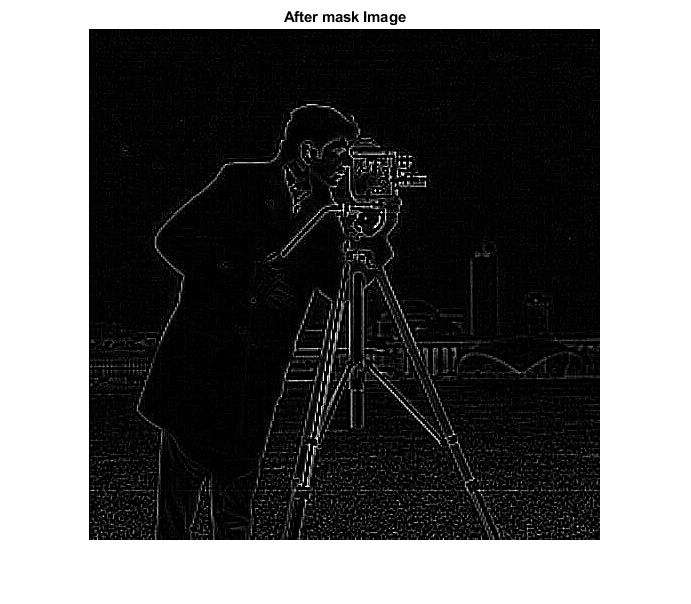

figure
imd=im2double(imgr);
[r,c]=size(imd);
padded=zeros(r+2,c+2);
padded(2:513,2:513)=imd;

figure
mask=[1 1 1; 1 -8 1; 1 1 1];
for i=2:r
    for j=2:c
        out(i-1,j-1)=mask(1,1)*padded(i-1,j-1)+mask(1,2)*padded(i-1,j)+mask(1,3)*padded(i-1,j+1)+mask(2,1)*padded(i,j-1)+mask(2,2)*padded(i,j)+mask(2,3)*padded(i,j+1)+mask(3,1)*padded(i+1,j-1)+mask(3,2)*padded(i+1,j)+mask(3,3)*padded(i+1,j+1);
    end
end
imshow(out);
title('After mask Image')


% Gaussian Filter

im2=imread("E:\Study\DIP\Lab_exp\cameraman.jpg");
imshow(im2);
title('Orignal Image')

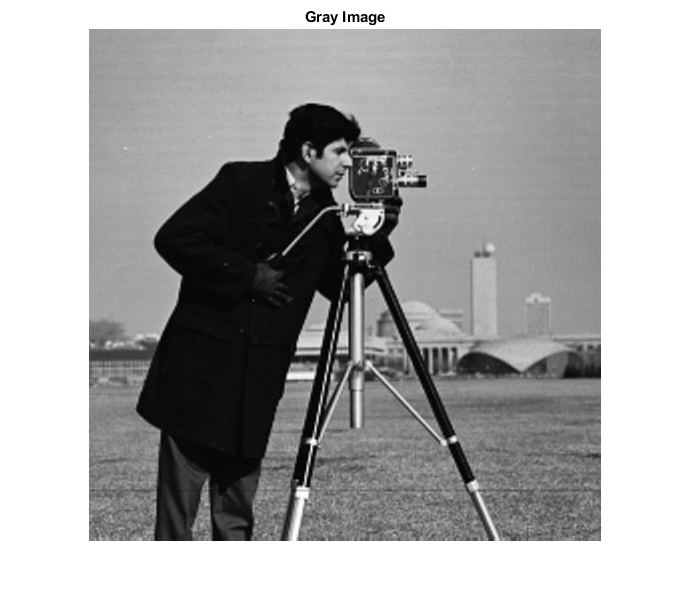

figure
imgr2=out;
imshow(imgr);
title('Gray Image')

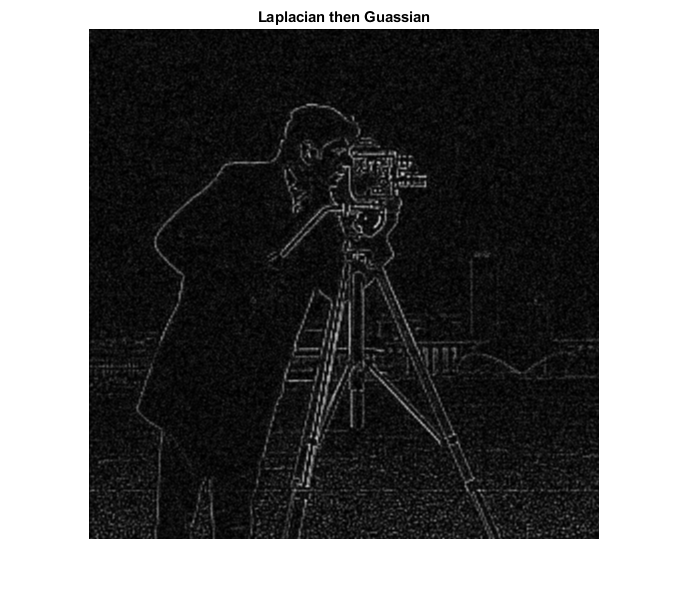

figure
imd2=im2double(imgr2);
noi2=imnoise(imd2,'gaussian');
[r,c]=size(noi2);
padded=zeros(r+2,c+2);
padded(2:512,2:512)=noi2;

figure
mask=[1 2 1; 2 4 2; 1 2 1];
for i=2:r
    for j=2:c
        out2(i-1,j-1)=mask(1,1)*padded(i-1,j-1)+mask(1,2)*padded(i-1,j)+mask(1,3)*padded(i-1,j+1)+mask(2,1)*padded(i,j-1)+mask(2,2)*padded(i,j)+mask(2,3)*padded(i,j+1)+mask(3,1)*padded(i+1,j-1)+mask(3,2)*padded(i+1,j)+mask(3,3)*padded(i+1,j+1);
    end
end
out2=out2/16;
imshow(out2);
title('Laplacian then Guassian')